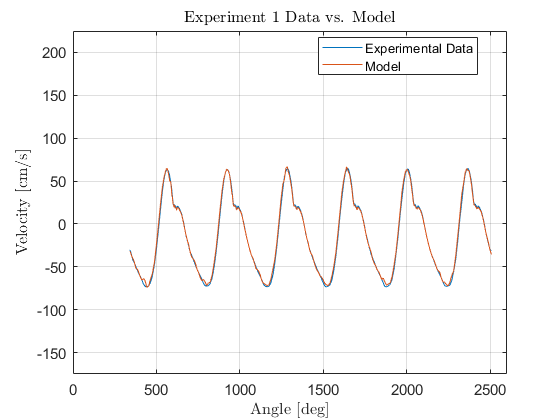

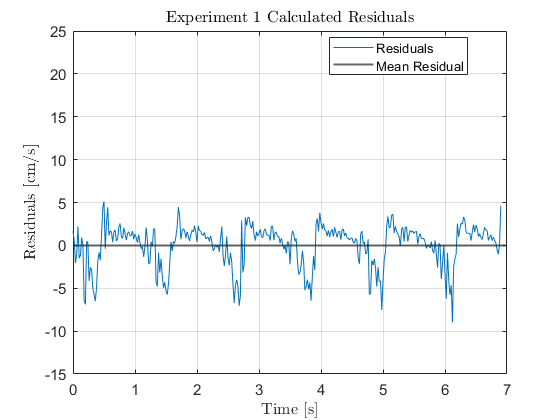

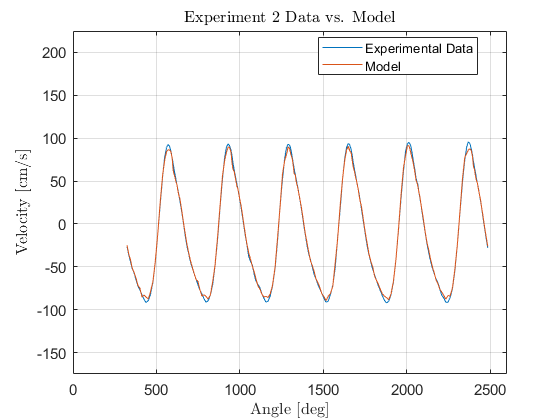

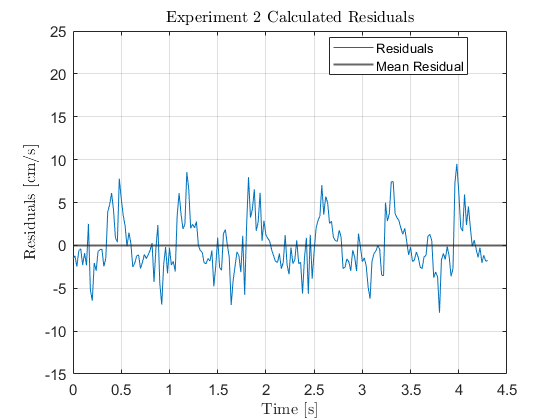

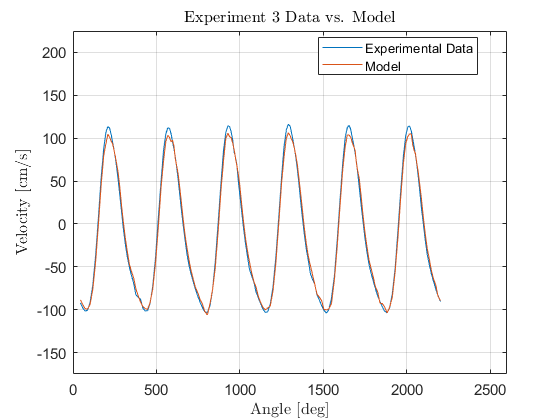

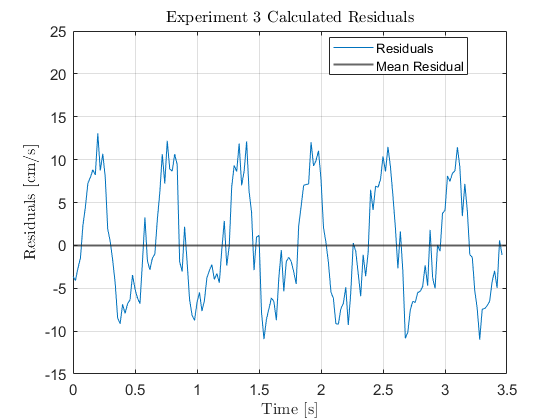

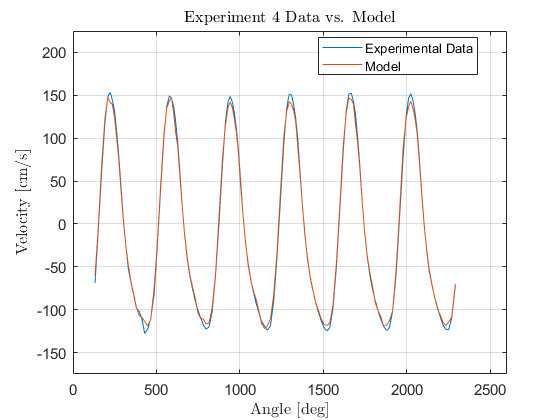

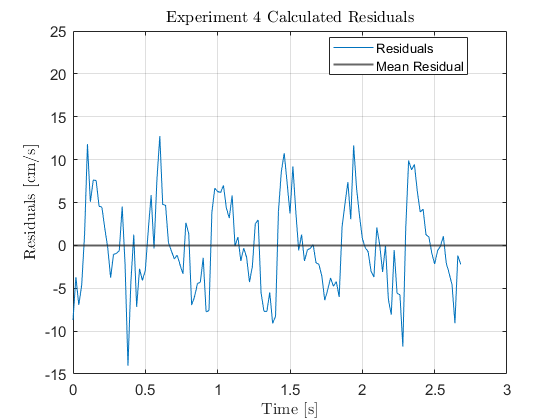

clear all
experiments = ["Test1_5pt5V","Test1_6pt5V","Test1_7pt5V","Test1_8pt5V","Test1_9pt5V","Test1_10pt5V"];
dataTable = table('Size',[6,3],'VariableTypes',{'double','double','double'},'VariableNames',["Experiment","ErrorMean","ErrorSTD"]);
for i = 1:6
    [theta,w,v,time] = LCSCalc(experiments(1,i));
    figure()
    plot(theta,v)
    xlim([0 2600]);
    ylim([-175, 225]);
    hold on
    set(0,'defaultTextInterpreter','latex')
    set(gca,'FontSize',11)
    title("Experiment " + i + " Data vs. Model")
    grid on
    vM = LCSMODEL(7.5,15.5,26,theta,w);
    plot(theta,vM)
    legend("Experimental Data","Model",'Location',"best")
    xlabel("Angle [deg]")
    ylabel("Velocity [cm/s]")
    hold off
    figure()
    residual = v - vM;
    plot(time,residual)
    hold on
    yline(mean(residual),"Linewidth",1.5)
    grid on
    legend("Residuals","Mean Residual","Location","best");
    set(0,'defaultTextInterpreter','latex')
    set(gca,'FontSize',11)
    title("Experiment " + i + " Calculated Residuals")
    ylim([-15, 25]);
    xlabel("Time [s]")
    ylabel("Residuals [cm/s]")
    hold off
    dataTable.Experiment(i,1) = i;
    dataTable.ErrorMean(i,1) = mean(residual);
    dataTable.ErrorSTD(i,1) = std(residual);
end

dataTable

dataTable = 6×3 table
    Experiment     ErrorMean     ErrorSTD
    __________    ___________    ________

        1            0.010023     2.4514 
        2          -0.0090456     3.1586 
        3         -0.00019671     6.4335 
        4           -0.044235     5.2515 
        5            0.065641     6.4728 
        6            -0.05129     7.6712 


function [theta_exp,w_exp,v_exp,time] = LCSCalc(fileName)
    % Reading in the file, interpreting columns
    data = readtable(fileName);
    data.Properties.VariableNames = ["Time","Theta","yDist","AngVel","SlideSpeed","SampleT"];
    % converting slide speed to cm/s
    data.SlideSpeed = data.SlideSpeed./10;
    % subtacting out extra rotations
    data.Theta = data.Theta - (floor((data.Theta(1,1))/360)*360);
    % determining the total amount of turns
    data.totalTurns = (data.Theta - data.Theta(1,1))./360;
    % finding where the disk completes 6 rotations
    [~,ind] = min(abs(data.totalTurns-6));
    % getting rid of all data beyond 6 rotations
    data([ind+1:end],:) = [];
    time = data.Time(:,1);
    theta_exp = data.Theta;
    w_exp = deg2rad(data.AngVel);
    v_exp = data.SlideSpeed;
end
function beta = betaCalc(d, r, l, theta)
% Function for calculating angle Beta

beta = asind( (d - r * sind(theta)) / l );

end
function vMod = LCSMODEL(r, d, l, theta, w)
% Function for calculating velocity of collar along y axis

beta = betaCalc(d, r, l, theta);
vMod = -1 * w.*r .* (cosd(theta).*tand(beta) + sind(theta));

end